# DOA Deep CNN Training (without use of trainnet or trainNetwork)

File Run Location: 

**C:\Users\mathe\Documents\MATLAB\Thesis Codes and Figures\ThesisDatasetsAndNeuralNetwork**

%%% Test different training data styles %%%
% 1. 3-Channel: Real,Imag,Phase
% 2 - 3-Channel: Real,Imag,Abs
% 3 - 2-Channel: Real,Imag
% 4 - 2-Channel: Abs,Phase
% 5 - 1-Channel: Phase 
% (maybe) 6 - Upper Triangular Cov Matrix 

## Supporting Functions:

function desired_struct_location = is_desired_struct(data)

function Y_denormalized = predictAngles(net, mbq) % Not Used yet until using test data

function [loss,gradients,state,Y] = modelLoss(net,X,T)

function [X,T] = preprocessMiniBatch(dataX,dataT)

function Y = modelPredictions(net,mbq) % Not Used yet (still need to save model & use test data not just validation)

function stop = stopTraining(info,lossThreshold) % Not used Yet (Early Validation Stopping / Validation Patience)

## Initialization

close all;clc; 
% clear all; % commented to prevent clearing out the workspace
cd("C:\Users\mathe\Documents\MATLAB\Thesis Codes and Figures\ThesisDatasetsAndNeuralNetwork");
% setup file for Matlab figures
set(0,'DefaultAxesFontSize',18)
set(0,'DefaultLineLineWidth',2)
set(0,'DefaultTextFontSize',18)
legend_font_size = 12;

% Use: setTightMargins(0.05) for consistent figures

## Load Training Data and Folder Names

train_filename = 'training_data_array_perturbations.h5';
validate_filename = 'validation_data_array_perturbations.h5';
% test_filename = 'testing_data_array_perturbations.h5';
% file_names = {train_filename,validate_filename,test_filename};
cd("HDF5_File_Location");

% load in data to struct using HDF2Struct:
% Syntax:  data = HDF2Struct(file_name, verbose)
train_data = HDF2Struct(train_filename); 
validate_data = HDF2Struct(validate_filename);

cd ..

overarching_foldername = 'Training_And_Validation_DataReal_Imag_Phase';
train_foldername = 'TrainingData5x5Image';
%train_foldername = 'TrainingData'; %-LargerFiguresIMAGESC 
% validate_foldername = 'ValidationData'; % larger figs IMAGESC 656x875 
validate_foldername = 'ValidationData5x5Image';


cd(overarching_foldername);

## Normalize output Labels for Network Training -> currently un-normalized

% Try with un-normalized Data for Validation and Training 
train_labels_deg = train_data.dataset_theta;
validate_labels_deg = validate_data.dataset_theta;

%{ 

% Normalize the desired labels between [0,1] then denormalize after
% training is complete % reverse operation to get back to degrees: 
min_label = -90; max_label = 90; 
train_labels_deg = train_data.dataset_theta;
train_labels = (train_labels_deg - min_label)/(max_label - min_label); % normalized :)
% Normalize Validation Dataset 
validate_labels_deg = validate_data.dataset_theta;
validate_labels = (validate_labels_deg - min_label)/(max_label - min_label);

%}

## Creating DataStores

Previous problem was using validation data when running trainnet() follow example "Train Network Using Custom Training Loop" to train in another way. There are still built in optimization (Adam,SGDM), display, and mini-batch creation. 

% Create Training Data datastore 
train_datastore_images = imageDatastore(train_foldername); % grabs directory, don't need to cd into it
% Create training labels for the angles themselves: Can change above to be
% normalized between [0,1] but that is quick & EZ 
train_labels_datastore = arrayDatastore(train_labels_deg,IterationDimension=3);
train_datastore = combine(train_datastore_images,train_labels_datastore); 

% Create Validate Data datastore 
validate_datastore_images = imageDatastore(validate_foldername); 
validate_labels_datastore = arrayDatastore(validate_labels_deg,IterationDimension=3);
validate_datastore = combine(validate_datastore_images,validate_labels_datastore);

cd .. % back out to main directory where this script is stored

## Plot Example Samples

Plot some example images from the dataset 

% assume always in [groups# samples#]
train_fieldnames = fieldnames(train_data);
train_num_groups_samples =  is_desired_struct(train_data); 
train_group_number = train_data.(train_fieldnames{train_num_groups_samples})(1);
train_sample_number = train_data.(train_fieldnames{train_num_groups_samples})(2);
train_num_samples = train_group_number * train_sample_number;

% Create plot (validate cov matrices will look similar: 
sample_fig = figure(100);
sample_fig.Name = 'Covariance Samples';
% plot this many random covariance matrices 
sample_numbers = 4; 
% set random seed 
rand_seed=11; rng(rand_seed,'twister');
% create 'sample_numbers' number of samples within range of 1:num_samples

rand_vals = randi([1 train_num_samples],1,sample_numbers); 
% plot respective cov multiplier and perturbation values & theta value 
cols = sample_numbers/(sample_numbers/2);
rows = sample_numbers/cols;
tiledlayout(rows,cols);

% iterate through sample cov matrices to plot 
for i = 1:sample_numbers
    nexttile
    %current_img = readimage(train_datastore,rand_vals(i));
    % Method 2: using the arrayDatastore for labels 
    current_img = readimage(train_datastore_images,rand_vals(i));
    imshow(current_img)

    % join string array with space in between values
    elem_perturb_combined = join(string(train_data.dataset_arr_perturb_elem(:,:,rand_vals(i))), ' ');
    % element_perturbations_string = strcat('Element Perturbations: [',elem_perturb_combined,' ]');
    element_perturbations_string = strcat('[',elem_perturb_combined,' ]');
    
    % create titles
    %title_string = [strcat('Theta: ',string(train_data.dataset_theta(:,:,rand_vals(i)))),...
    %    strcat('Array Perturbation Multiplier: ',string(train_data.dataset_arr_perturb_mult(:,:,rand_vals(i)))),...
    %    element_perturbations_string ];
    % Required to use "" string instead of '' char for space to be applied
    title_string = [strcat("Img Number: ",string(rand_vals(i))),...
        strcat("Theta: ",string(train_data.dataset_theta(:,:,rand_vals(i)))),...
        strcat("Perturb Mult: ",string(train_data.dataset_arr_perturb_mult(:,:,rand_vals(i))))];
    title(title_string,FontSize=12);

end
% print actual covariance matrix of last sample
indx = rand_vals(i);
% previously overall_cov_matrix
A = train_data.dataset_cov_real(:,:,indx) + 1j*train_data.dataset_cov_imag(:,:,indx);

% Define format string with placeholders for real and imaginary parts
formatSpec = '%+.2f%+0.2fj ';

% Loop through each row
for i = 1:size(A, 1)
  row_string = [];
  % Loop through each element in the row (col)
  for j = 1:size(A, 2)
    % Format complex number (real+j*imag) with 2 decimal places
    formattedElement = sprintf('%.2f%+0.2fj', real(A(i, j)), imag(A(i, j)));
    % Print the formatted element with space
    row_string = [row_string formattedElement ' '];
  end
  % Remove trailing space using strtrim
  %row_string = strtrim(row_string);  % Remove extra space at the end
  % Print the row string with newline
  fprintf([row_string '\n']);
end

1.00+0.00j -0.83+0.55j 0.82+0.57j -0.48-0.87j 0.90-0.43j 
-0.83-0.55j 1.01+0.00j -0.37-0.93j -0.08+1.00j -0.99-0.14j 
0.82-0.57j -0.37+0.93j 1.01+0.00j -0.89-0.45j 0.50-0.87j 
-0.48+0.87j -0.08-1.00j -0.89+0.45j 1.01+0.00j -0.06+1.00j 
0.90+0.43j -0.99+0.14j 0.50+0.87j -0.06-1.00j 1.02+0.00j 



disp("Conjugate Symmetry Exhibited");

Conjugate Symmetry Exhibited


disp("Hard to notice when normalized for images");

Hard to notice when normalized for images


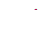


% impixelinfo(sample_fig);
saveas(sample_fig,'ArrayCovariancePerturbedSamplesTraining.jpg'); 

## Define Model Loss Function (from Custom Training Loop Example) 

Training a deep neural network is an optimization task. By considering a neural network as a function $f(X;\theta)$, where $X$ is the network input, and $\theta$ is the set of learnable parameters, you can optimize $\theta$ so that it minimizes some loss value based on the training data. For example, optimize the learnable parameters $\theta$ such that for a given inputs $X$ with a corresponding targets $T$, they minimize the error between the predictions $Y = f(X;\theta)$ and $T$.

Create the function `modelLoss`, listed in the Model Loss Function section of the example, that takes as input the `dlnetwork` object, a mini-batch of input data with corresponding targets, and returns the loss, the gradients of the loss with respect to the learnable parameters, and the network state.

## Define Network Layers

- Simple Initial Network with Input Layer, conv2D_1, BN_1, ReLU_1, conv2D_2, BN_2, ReLU_2, conv2D_3, BN_3, ReLU_3, conv2D_4, BN_4, ReLU_4, fullyConnectedLayer_1 

- Later: add more fully connected layers 3-4 seemed to work for other papers 


% A dlnetwork object specifies a deep learning neural network architecture
network_topology = dlnetwork;
output_signals = 1;
N = size(train_data.dataset_arr_perturb_elem,2);
channels = 3; % change based on desired image size from those created in image datastore 
imput_img_size = [N N channels];

%%% Simpler Network to avoid overfitting - 32 3x3 Conv2D - 64 1x1 Conv2D -
%%% 2 FC-Layers from output of CNN down to "output_signals" size
% Output of CNN: #Filters * Img Size (5x5)
% 64 * (5*5) = 1600 for 64 1x1 Conv - Increase FCL1 to 512 Doubled
% Parameters 823.4k from 413.3k Learnables

% ReLU: thresholds weights to prevent negative values 
% Dropout for 0.5 for Fully Connected Layer 
% Try Global Average Pooling instead of FullyConnectedLayer? 
deep_cnn_layers1 = [ 
    imageInputLayer(imput_img_size,Normalization="none", Name='ImageInput')
    convolution2dLayer([3 3],32,Name='Conv2D_3x3_32_1st',Padding='same')
    batchNormalizationLayer(Name="BatchNorm1")
    reluLayer(Name="ReLU1")
    convolution2dLayer([1 1],64,Name='Conv2D_1x1_64_2nd',Padding='same')
    batchNormalizationLayer(Name="BatchNorm2")
    reluLayer(Name="ReLU2")
    fullyConnectedLayer(256,Name='FullyConnected1_1600to256')
    dropoutLayer(0.5,Name="Dropout1")
    fullyConnectedLayer(output_signals,Name='FullyConnected2_256to1')
    ]; 
network_topology = addLayers(network_topology,deep_cnn_layers1);

% initialize the neural network 
network_topology = initialize(network_topology);


## Viewing the Network and Visualization Tools

% viewing initialized weights for all filters in 1st conv layer: 
% network_topology.Learnables.Value{1}
% show the relevant network
analyzeNetwork(network_topology);

## Define Training Options

Epochs, mini-batch size, initial learning rate, decay, momentum

Note for Custom Training Loop Progress / Validation Accuracy: [Monitor Cusom Training Loop Progress](https://www.mathworks.com/help/deeplearning/ug/monitor-custom-training-loop-progress.html) (figure out later - feature) 

% Overall Optimizer Parameters 
num_epochs = 10; 
mini_batch_size_training = 128; 
% SGDM 
initial_learning_rate = 1e-3; 
decay = 0.01;
momentum = 0.9; 

% ADAM 

## Train Model Parameters: MBQ,  

Create a [`minibatchqueue`](docid:nnet_ref#mw_412afe49-5c0e-4f1b-8df7-b229f1b07eec) object that processes and manages mini-batches of images during training. For each mini-batch:

- Use the custom mini-batch preprocessing function `preprocessMiniBatch` (defined at the end of this example) to convert the labels to one-hot encoded variables.

- Format the image data with the dimension labels `"SSCB"` (spatial, spatial, channel, batch). By default, the `minibatchqueue` object converts the data to `dlarray` objects with underlying type `single`. Do not format the class labels.

- Discard partial mini-batches. (return has mini-batches that can have less than the size indicated)

- Assume same "MiniBatchFormat" only differences is out channels (C) will not be 1 for grayscale 

- Calculate the total number of iterations for the training progress monitor.


%mbq = minibatchqueue(train_arr_datastore,...
%    MiniBatchFcn=@preprocessMiniBatch, ...
%    MiniBatchSize=mini_batch_size,...
%    MiniBatchFormat=["SSCB" ""],...
%    PartialMiniBatch="discard");

%train_datastore
%train_arr_datastore
mbq = minibatchqueue(train_datastore,...
    MiniBatchFcn=@preprocessMiniBatch, ...
    MiniBatchSize=mini_batch_size_training,...
    MiniBatchFormat=["SSCB" ""],...
    PartialMiniBatch="discard");

%numObservationsTrain = numel(imdsTrain.Files); % no imdsTrain since all
numObservationsTrain = size(readall(train_datastore.UnderlyingDatastores{1}),1);
numIterationsPerEpoch = floor(numObservationsTrain / mini_batch_size_training);
numIterations = num_epochs * numIterationsPerEpoch;

% Set Validation Frequency / # iterations
validation_freq = 10; 

% validation size, just one mbq use 
mini_batch_size_validate = ceil(numIterations/validation_freq);
% Create validation Dataset single MiniBatchQueue
mbq_validate = minibatchqueue(validate_datastore,...
    MiniBatchFcn=@preprocessMiniBatch, ...
    MiniBatchSize=mini_batch_size_validate,...
    MiniBatchFormat=["SSCB" ""],...
    PartialMiniBatch="discard");

% Future - modify "mini_batch_size_validate" based on
% "numIterations/validation_freq"
disp("Number of Training Observations Total: "+string(numObservationsTrain))

Number of Training Observations Total: 25000


disp("Number of Epochs: "+string(num_epochs))

Number of Epochs: 10


disp("Mini Batch Size Training: "+string(mini_batch_size_training));

Mini Batch Size Training: 128


disp("Mini Batch Size Validation (one mbq): "+string(mini_batch_size_validate));

Mini Batch Size Validation (one mbq): 195


disp("Number of Iterations Per Epoch: "+string(numIterationsPerEpoch))

Number of Iterations Per Epoch: 195


disp("Total Number of Iterations: "+string(numIterations))

Total Number of Iterations: 1950


disp("Number Validation Points (25 iterations): "+string(numIterations/validation_freq))

Number Validation Points (25 iterations): 195


iteration = 0;

## Initializing Monitor for Training & Validation Progress

Note: Accuracy cannot be plotted in the case of a regression network 

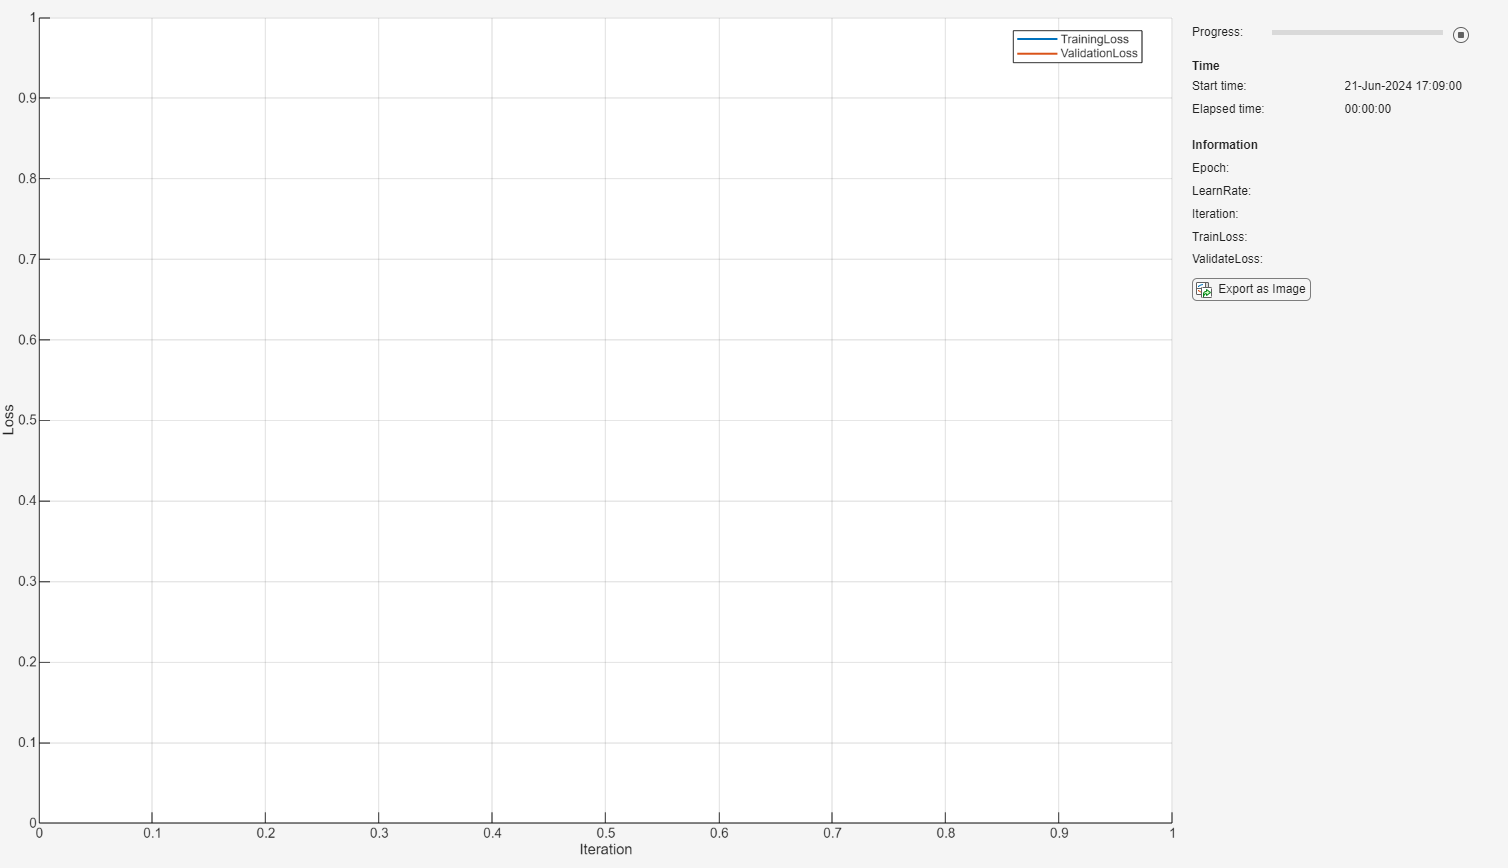

% Add Metrics ValidationLoss
% Add Progress % & add subplot for accuracy
% not sure if "Loss" in Info is needed for the monitor? 
monitor = trainingProgressMonitor( ...
    Metrics=["TrainingLoss","ValidationLoss"], ...
    Info=["Epoch" "LearnRate" "Iteration" "TrainLoss" "ValidateLoss"], ...
    XLabel="Iteration", ...
    Progress=100*(iteration/numIterations));


% Subplot for for Validation Loss 
groupSubPlot(monitor,"Loss",["TrainingLoss","ValidationLoss"]); 

## Training the Network

Train the network using a custom training loop. For each epoch, shuffle the data and loop over mini-batches of data. For each mini-batch:

- Evaluate the model loss, gradients, and state using the `dlfeval` and `modelLoss` functions and update the network state.

- Determine the learning rate for the time-based decay learning rate schedule.

- Update the network parameters using the `sgdmupdate` function.

- Update the loss, learn rate, and epoch values in the training progress monitor.

- Stop if the Stop property is true. The Stop property value of the `TrainingProgressMonitor` object changes to true when you click the Stop button.

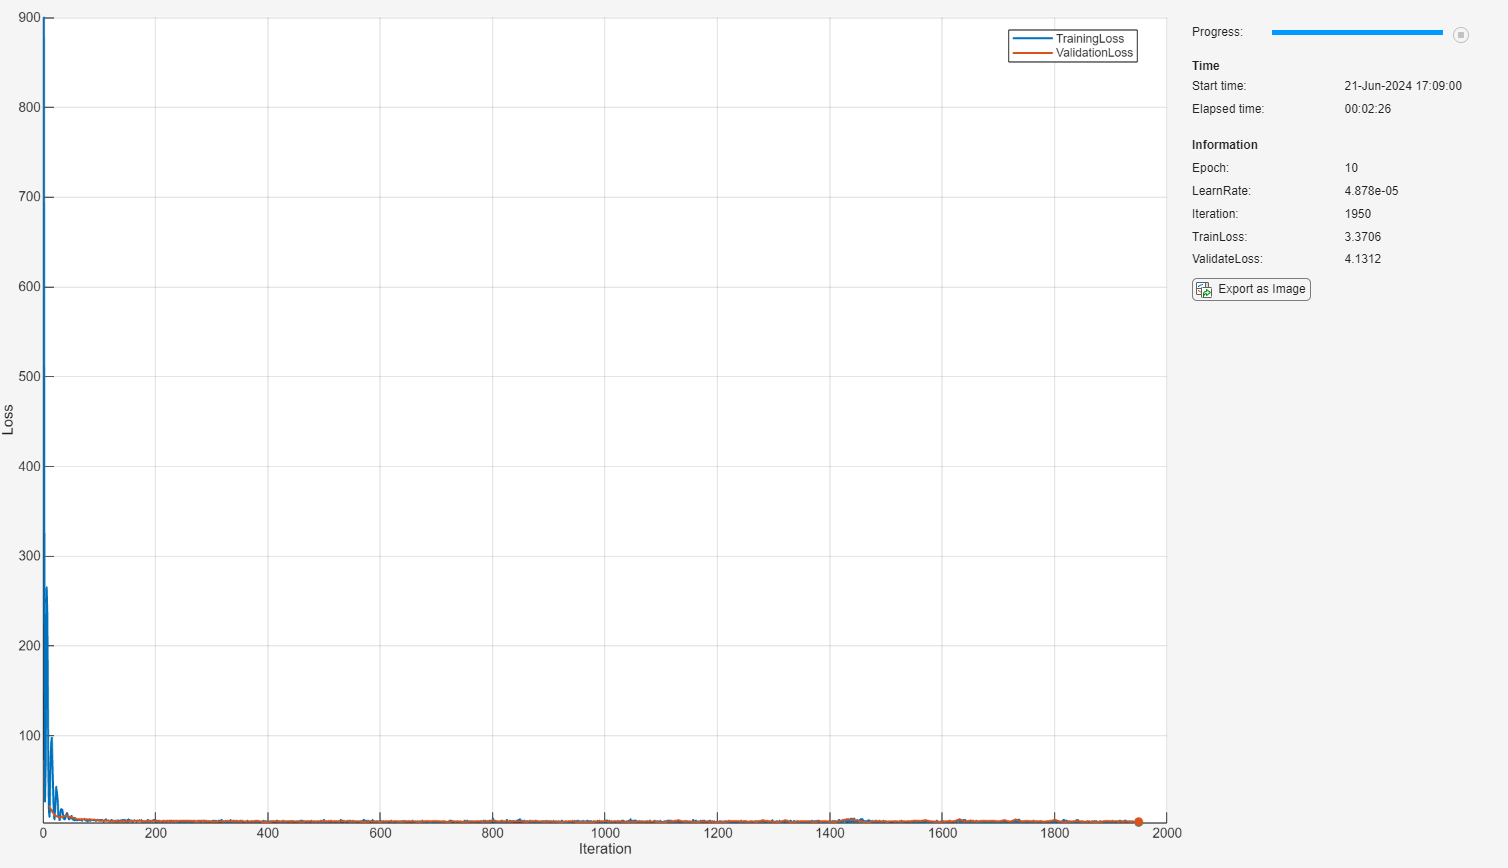

% initialize epochs to be 0
epoch = 0;
% for Adam Optimizer - initialize previous gradients to be empty 
averageGrad =[];
averageSqGrad = []; 

% gather validation minibatchqueue just once
% Create one validation MBQ - of required size as determined earlier
[X_validate,T_validate] = next(mbq_validate);

% Loop over epochs 
while epoch < num_epochs && ~monitor.Stop
    % early stopping: loss < lossThreshold
    % ValidationPatiency 
    epoch = epoch + 1;
    % Shuffle data.
    shuffle(mbq);
    % Loop over mini-batches.
    while hasdata(mbq) && ~monitor.Stop
        iteration = iteration + 1;      
        % X = 5x5x3x128 mbq object (images concatenated on 4th dim) 
        % T = 128 1xnum_signals] normalized angle values/labels
        [X,T] = next(mbq);
        
        % Validate mbq if modulus 0 for validation_frequency: 
        if mod(iteration,validation_freq) == 0     
            % Just use a single large minibatch like 512 or 1024 that will
            % be a multiple of the # iterations / validation_freq: 
            % create next minibatchqueue from validation dataset 1250 
            % [X_validate,T_validate] = next(mbq_validate);

            % run through function to get loss,accuracy
            % Y_validate is last argument for outputs of "modelLoss" function
            % The Y-value is the output of the Deep CNN
            [validation_loss,~,~,~] = dlfeval(@modelLoss,network_topology,X_validate,T_validate);
            
            % Troubleshooting for suspiciously high validation error
            %disp("Output Value: "+string(Y_validate));
            
            % don't update the state for validation data - % network_topology.State = state; 
            % Update the training progress monitor.
            recordMetrics(monitor,iteration,ValidationLoss=validation_loss);
            updateInfo(monitor,...
                Epoch=epoch,...
                LearnRate=learnRate,...
                Iteration=iteration, ...
                ValidateLoss=validation_loss);
        end

        % Evaluate the model gradients, state, and loss using dlfeval and the
        % modelLoss function and update the network state.
        % replace net with network_topology (only here not in functions)
        % use @function: 
        % function [loss,gradients,state] = modelLoss(net,X,T)
        [training_loss,gradients,state,~] = dlfeval(@modelLoss,network_topology,X,T);
        network_topology.State = state;
        
        % Viewing size of 1st Conv Layer 1st filter's gradients
        % Explode after 4-5 iterations to inf/NaN
        % disp(gradients.Value{1}(:,:,:,1));

        % Determine learning rate for time-based decay learning rate schedule.
        learnRate = initial_learning_rate/(1 + decay*iteration);
        
        % Update the network parameters using the SGDM optimizer.
        %[network_topology,velocity] = sgdmupdate(network_topology,gradients,velocity,learnRate,momentum);
        
        % [netUpdated,averageGrad,averageSqGrad] = ...
        % adamupdate(net,grad,averageGrad,averageSqGrad,iteration)
        % Try Using Adam since exploding gradients

        [network_topology,averageGrad,averageSqGrad] = ...
            adamupdate(network_topology,gradients,averageGrad,averageSqGrad,iteration);

        % Try RMSProp? 

        % Update the training progress monitor.
        recordMetrics(monitor,iteration,TrainingLoss=training_loss);
        % Info is different from recordMetrics
        updateInfo(monitor,...
            Epoch=epoch,...
            LearnRate=learnRate,...
            Iteration=iteration, ...
            TrainLoss=training_loss);
        monitor.Progress = 100 * iteration/numIterations;
    end
end

## Save Model: 

% Save the entire workspace to the file DCNNThesisWorkspace.mat
save('DCNNThesisWorkspace');
% Save just the neural network topology and weights about 1.7MB
save("DeepCNNArrayPerturb1.mat",'network_topology'); 

## Load Model:

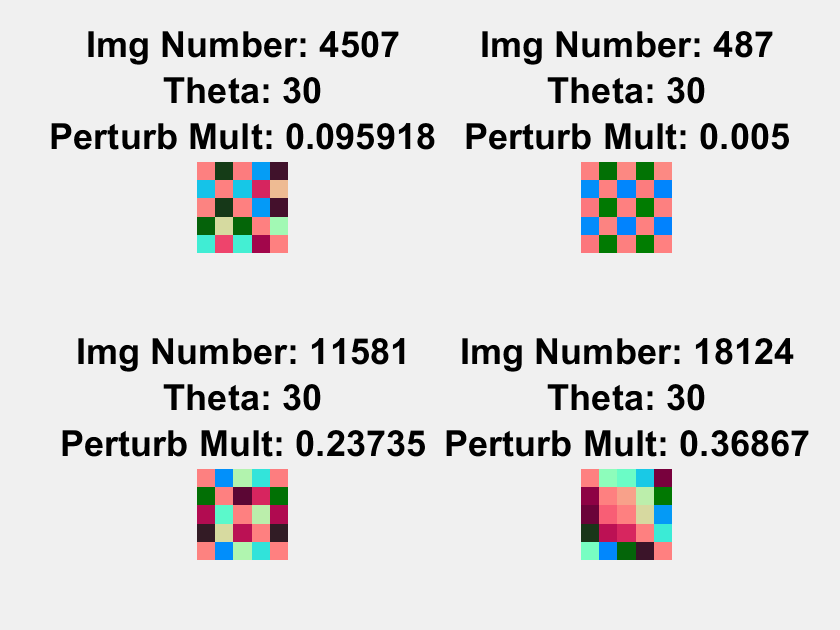

% Load network into Workspace
% cd("C:\Users\mathe\Documents\MATLAB\Thesis Codes and Figures\ThesisDatasetsAndNeuralNetwork")

% Uncomment for entire workspace:
load DCNNThesisWorkspace.mat

% Uncomment for just Neural Network: 
% load DeepCNNArrayPerturb1.mat

## Visualize Conv 1 3x3 Layer 2 Before ReLU Activation Function - Normalized 

Viewing the 1st convolution layer in order to visualize network performance

Originally attempted to grab a random validation & test sample and use this for visualizing convolution filters in the first layer, but decided instead to visualize the filters individually without external influence. 

% Known First Convolution Layer 32 - 3x3 Kernels is Layer 2 (right after
% Image Input Layer)
analyze_layer_num = 2;
% Determine the Layer's Name
analyze_layer_name = network_topology.Layers(analyze_layer_num).Name;
% Obtain the Layer parameters (weights, filter size, channels, etc.)
view_network = getLayer(network_topology,analyze_layer_name);

% View Just the 3x3 weights:
plotTiledFigConv1Weights = figure(775);
conv1Weights = view_network.Weights; 
% Have to normalize weights in range [0,1] since some are negative
maxWeight = max(conv1Weights,[],'all'); minWeight = min(conv1Weights,[],'all');
conv1WeightsNorm = (conv1Weights-minWeight) ./ (maxWeight-minWeight);
% since 3D channel 
conv1_filter_size = size(conv1WeightsNorm,4); 
t2 = tiledlayout(round(conv1_filter_size/8),round(conv1_filter_size/4));
t2.TileSpacing = 'tight';
title(t2,"Conv Layer 1 Activations 3x3x3 Normalized");
for i = 1:conv1_filter_size
    nexttile
    imshow(conv1WeightsNorm(:,:,:,i));
end
%impixelinfo;
setTightMargins(0.05);

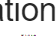

saveas(plotTiledFigConv1Weights,"Convolution1_32_3x3Kernel_Normalize_PriorReLU.jpg");


% View just real channel
fig_test_conv1 = figure(875);
t3 = tiledlayout(round(conv1_filter_size/8),round(conv1_filter_size/4));
t3.TileSpacing = 'tight';
title(t3,"Conv Layer 1 Activations 3x3x1 (Real) Normalized");
for i = 1:conv1_filter_size
    nexttile
    imshow(conv1WeightsNorm(:,:,1,i));
end
%impixelinfo;
setTightMargins(0.05);

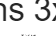

saveas(fig_test_conv1,"RealComponentConvolution1_32_3x3Kernel_Normalize_PriorReLU.jpg");

## Grabbing convolution filters after their ReLU layers - & Normalization

convertWeights = dlarray(double(view_network.Weights));
conv1WeightsReLU = relu(convertWeights); 
outputShowReLU = extractdata(conv1WeightsReLU); 

% Plot Convolution Layer after Passed Through ReLU Layer - all 3 channels %
fig_test_RELU = figure(975);
t4 = tiledlayout(round(conv1_filter_size/8),round(conv1_filter_size/4));
% 'tight' and 'compact' spacing exist, default is 'loose'
t4.TileSpacing = 'tight';
title(t4,"Conv Layer 1 Activations 3x3x3 Normalized After ReLU");
for i = 1:conv1_filter_size
    nexttile
    maxReLU = max(outputShowReLU(:,:,:,i),[],'all'); 
    minReLU = min(outputShowReLU(:,:,:,i),[],'all');
    normReLU = (outputShowReLU(:,:,:,i)-minReLU) / (maxReLU-minReLU);
    imshow(normReLU);
    % Before normalization - washed out - very dark, hard to visualize
    % imshow(outputShowReLU(:,:,:,i));
end
%impixelinfo;
setTightMargins(0.05);

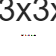

saveas(fig_test_RELU,"Convolution1_32_3x3Kernel_Normalize_AfterReLU.jpg");

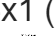


%%% --------------------------------------------- %%%

% Plot Convolution Layer after Passed Through ReLU Layer - Real Channels %
fig_test__Real_PostRELU = figure(976);
t5 = tiledlayout(round(conv1_filter_size/8),round(conv1_filter_size/4));
% 'tight' and 'compact' spacing exist, default is 'loose'
t5.TileSpacing = 'tight';
title(t5,"Conv Layer 1 Activations 3x3x1 (Real) Normalized After ReLU");
for i = 1:conv1_filter_size
    nexttile
    maxReLU = max(outputShowReLU(:,:,1,i),[],'all'); 
    minReLU = min(outputShowReLU(:,:,1,i),[],'all');
    normReLU = (outputShowReLU(:,:,1,i)-minReLU) / (maxReLU-minReLU);
    imshow(normReLU);
    % Before normalization - washed out - very dark, hard to visualize
    % imshow(outputShowReLU(:,:,1,i)); % only first channel for real part
end
%impixelinfo;
setTightMargins(0.05);

saveas(fig_test__Real_PostRELU,"RealComponentConvolution1_32_3x3Kernel_Normalize_AfterReLU.jpg");

Error using print (line 82)
Functionality not supported with figures created with the uifigure function.

Error in saveas (line 181)
        print( h, name, ['-d' dev{i}] )

## Test Model

Show input covariance matrices, network estimates, actual labels, and absolute error value with respect to average array perturbation multiplier. Display the actual perturbations on the cmd window using `fprintf`

- Compare to MUSIC and ESPRIT for each case and have a variable "Result" that summarizes the results at the end (also the option for fprintf just commented out) -> Just make it easier and have them separate 

% Just print out the exact perturbations don't put them on the tiled figure

% Set number of samples desired to test network performance of 
test_sample_num = 4; 
% Size of Validation Dataset:
validate_size = size(validate_data.dataset_theta,3);
test_img_numbers = floor(validate_size * rand(1,test_sample_num));

% Redfine RandVals for Testing Dataset: 
rand_vals = randi([1 train_num_samples],1,test_sample_num); 

%%% Show Images of Test Samples 
% Create plot (validate cov matrices will look similar: 
test_fig = figure(1000);
test_fig.Name = 'Test Covariance Samples';
% Half number of columns as rows 
cols_test = test_sample_num/(test_sample_num/2);
rows_test = test_sample_num/cols_test;
tiledlayout(rows_test,cols_test);

% Pre-allocate Strings to print for actual perturbations for each test image: 
element_perturbations_string = strings(1,test_sample_num);

for i=1:test_sample_num
    nexttile; %move tiles to next for plotting   
    current_img_number = test_img_numbers(i);
    current_image = readimage(validate_datastore.UnderlyingDatastores{1},current_img_number);
    imshow(current_img);
    % Convert image to double for use in dlarray for forward propaget thru network
    current_sample = dlarray(double(current_image));  

    % Run Image through network using: "dlfeval", "forward", "predict" - all 3 would work
    % [test_rmse_loss,~,~,Y_test] = dlfeval(@modelLoss,network_topology,...
    %    current_sample, current_label);  
    %Y = forward(network_topology,current_sample); % required MBQ or SSCB formatting
    Y = predict(network_topology,current_sample);

    % Estimated Labels 
    % Note just use the pre-known HDF5 labels, since reading datastore is challenging to index
    current_dataset_theta_label = validate_data.dataset_theta(:,:,current_img_number);
    % Perturbations aren't stored in the datastore, but are in HDF5 file
    current_dataset_perturbed_pos = validate_data.dataset_arr_perturb_elem(:,:,current_img_number);
    current_error = abs(Y-current_dataset_theta_label);

    % join string array with space in between values & print perturbations
    % to cmd window 
    element_perturbations_string(i) = strcat('Element Perturbations: [ ',join(string(current_dataset_perturbed_pos)),' ]');
    fprintf('Current Perturbations: \n %s \n',element_perturbations_string(i));

    % create titles
    zero_line = "Img Number: " + string(current_img_number)
    first_line = "Estimated Label: " + string(Y);
    second_line = "Dataset Label: " + string(current_dataset_theta_label);
    third_line = "Error: " + string(current_error);
    fourth_line = strcat('Avg Perturb Mult: ',string(validate_data.dataset_arr_perturb_mult(:,:,test_img_numbers(i))));
       
    % use string array for newline in the title
    % use avg perturbation multiplier in title
    title([zero_line first_line second_line third_line fourth_line],FontSize=12);

end

% Saving image, ensuring correct size for figure, and viewing pixel values
% if impixelinfo is uncommented (shows up on figure during save command
setTightMargins(0.05);
saveas(test_fig,'ArrayCovariancePerturbedSamplesTesting.jpg');
% impixelinfo(test_fig);

## Testing Compared to MUSIC and ESPRIT

Example Use Case

% function [music_doa_estimation,angle_out] = MUSIC_DOA_Estimate(signal_in,varargin)
% function angle_out = ESPRIT_DOA_Estimate(signal_in,varargin)

% take MUSIC spectrum for each sample_per_multiplier
% [music_doa_estimation,angle_out_current] = MUSIC_DOA_Estimate(signal_in,...
%    rand_seed,search_space, theta_in,element_position,SNR_in);
		
% take ESPRIT spectrum - angle_out_current only possible output of ESPRIT function 
%angle_out_current_ESPRIT = ESPRIT_DOA_Estimate(signal_in,rand_seed,...
%    theta_in,element_position,SNR_in);

Use For determining errors from sample samples from the testing samples: 

% Pre-allocating comparison standards 
MUSICTestDOAEstimates = zeros(1,test_sample_num); 
MUSICTestDOAErrors = zeros(1,test_sample_num); 
ESPRITTestDOAEstimates = zeros(1,test_sample_num);
ESPRITTestDOAErrors = zeros(1,test_sample_num);
results = strings(1,test_sample_num);

% Creating original non-perturbed values -> use file/function: "initialize_params.m"
% Then just grab element perturbations 
theta_signals = 30; N = 5; d_exp = 0.5; SNR_in = 20; sig_amp = ones(1,length(theta_signals)); num_snapshots = 1000;
search_space = linspace(-90,90,181); % 1 degree resolution over search space
% rand_seed=11; % defined above
[signal_in,noise,x_expected] = initialize_params(theta_signals,N,d_exp,SNR_in,sig_amp,rand_seed,num_snapshots);

for i = 1:test_sample_num
    
    % Take the datasamples Covariance Matrix based on the HDF5 file, not
    % the image pixel values, not helpeful for MUSIC and ESPRIT 
    curr_samp_num = test_img_numbers(i);
    % Don't need current covariance matrix, just reconstruct the known
    % signal for the case of comparison sake (and since known to be same)

    % Estimated Labels 
    % Note just use the pre-known HDF5 labels, since reading datastore is challenging to index
    current_dataset_theta_label = validate_data.dataset_theta(:,:,curr_samp_num);
    
    % Perturbations aren't stored in the datastore, but are in HDF5 file
    current_dataset_perturbed_pos = validate_data.dataset_arr_perturb_elem(:,:,curr_samp_num);
    
    % Compute MUSIC DOA Estimate 
    theta_in = current_dataset_theta_label;
    element_position = x_expected + current_dataset_perturbed_pos;
    % Don't need entire MUSIC subspectra 
    [~,MUSICTestDOAEstimates(i)] = MUSIC_DOA_Estimate(signal_in,...
        rand_seed,search_space, theta_in,element_position,SNR_in);

    % find first value and use as DOA estimate - if multiple peaks determined
    % Technically should update MUSIC should use largest M peaks for M
    % signals and the smallest eigenvector to create the subspace to
    % determine the largest M peaks 
    % PROBLEM: THIS JUST GIVES INDX: 
    % MUSICTestDOAEstimates(i) = find(~isnan(MUSIC_angles),1,'first'); 
    
    % Compute ESPRIT DOA Estimate
    ESPRITTestDOAEstimates(i) = ESPRIT_DOA_Estimate(signal_in,rand_seed,...
        theta_in,element_position,SNR_in);
    
    % Compute Errors for MUSIC and ESPRIT 
    MUSICTestDOAErrors(i) = abs(MUSICTestDOAEstimates(i) - current_dataset_theta_label);
    ESPRITTestDOAErrors(i) = abs(ESPRITTestDOAEstimates(i) - current_dataset_theta_label);
    
    % print MUSIC and ESPRIT DOA estimates & Errors
    avg_perturbation_mult = validate_data.dataset_arr_perturb_mult(:,:,curr_samp_num);
   
    %fprintf("Image Number: %d \n",curr_samp_num);
    %fprintf("Average Perturbation Multiplier: %2.2f \n",avg_perturbation_mult)
    %fprintf("MUSIC DOA Estimate: %2.2f | MUSIC Abs Error: %2.2f \n",...
    %    MUSICTestDOAEstimates(i),MUSICTestDOAErrors(i));
    %fprintf("ESPRIT DOA Estimate: %2.2f | ESPRIT Abs Error: %2.2f \n",...
    %            ESPRITTestDOAEstimates(i),ESPRITTestDOAErrors(i));
    
    % Different Results Printing Method: 
    results(i) = strcat("sample num: ",string(curr_samp_num), ...
        "| perturb mult: ",string(avg_perturbation_mult),...
        "| MUSIC estimate: ",string(MUSICTestDOAEstimates(i)),...
        "| MUSIC error: ",string(MUSICTestDOAErrors(i)),...
        "| ESPRIT estimate: ",string(ESPRITTestDOAEstimates(i)),...
        "| ESPRIT error: ",string(ESPRITTestDOAErrors(i))...
        );
    disp(results(i));
end

# Supporting Functions

Using Cutom Training Loop Pre-Built Parameters: [Specify Training Options in Custom Training Loop](https://www.mathworks.com/help/deeplearning/ug/specify-training-options-in-custom-training-loop.html)

The functions below used in this livescript are: 

- Model Loss 

- Mini Batch Preprocessing 

- Is Desired Struct 

Functions used defined externally to the livescript 

- MUSIC - Compare Model Performance

- ESPRIT - Compare Model Performance

## Model Loss

The `modelLoss` function takes a `dlnetwork` object `net`, a mini-batch of input data `X` with corresponding targets `T` and returns the loss, the gradients of the loss with respect to the learnable parameters in `net`, and the network state. To compute the gradients automatically, use the `dlgradient` function.

- Given a minibatch object input X with labels T and a network topology in the `dlnetwork` determine: 

- Regression MSE loss, used for the optimizer to update parameter gradients 

- Each Learnables' gradient value for adjusting the parameter, 

- Network state, used for updating the Batch Normalization Parameters and current µ and σ

- Network Output Y used for determining loss or can be used in place of `forward` or `predict` built-in MATLAB functions to test a network's performance

function [loss,gradients,state,Y] = modelLoss(net,X,T)

% Forward data through network: multiply by Conv Filters & MLP for output
% regression output 
[Y,state] = forward(net,X); 


% Calculate MSE Regression loss, root MSE is another regression loss
% function that is commonly used for evaluating performance
loss = mean((Y - T).^2,'all');

% Calculate gradients of loss with respect to learnable parameters.
gradients = dlgradient(loss,net.Learnables);

end

## Mini Batch Preprocessing

The `preprocessMiniBatch` function preprocesses a mini-batch of predictors and labels using the following steps:

- Preprocess the images using the `preprocessMiniBatchPredictors` function.

- Instead of using one-hot encoding: use normalization based on range of expected labeled input regression data 

- After comparing to the labe, denormalize the value back to the range from [-90°,90°]

function [X,T] = preprocessMiniBatch(dataX,dataT)
  %dataX - {5x5x3x25000 uint8} (1x1 cell array)
  %dataT - {1x1x2500 double} (1x1 cell array)
  
  X = cat(4,dataX{:});
  % concatenate labels on 3rd axis for case of M>1 source
  T = cat(3,dataT{:});
end

## is_desired_struct

Used to plot the correct fields of the struct when creating labels for image samples

%% Check for string in a desired struct - for finding number of groups and datasets if the value changes
function desired_struct_location = is_desired_struct(data)
    % finds the location where "groups" and "num_samples" is contained in
    % case this string value changes for the name of the field in the
    % struct containing the samples
    % easier than using regular expressions
    field_names = fieldnames(data); 
    desired_struct_location = find(contains(field_names,"groups")&contains(field_names,"num_samples"));
end


## Other Desired Functions:

- Early Stopping based on Validation Patience and validation loss over multiple epochs 

- Function maybe for Testing data so can be called multiple times instead of manually 